# Cameras

We render the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

This script  illustrates how to set the focal distance, and it reveals the depth of field for this double Gauss lens.

## Set up ISETCam

Also, make sure we have docker running.

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the PBRT scene

thisR = piRecipeDefault('scene name','ChessSet');

Read 9 materials and 3 textures..


thisR.set('spatial resolution',1024);

## Create a camera with a double Gauss lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

The distance that will be in focus

thisR.set('focus distance',0.8);

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

thisR.set('from',[0,0.18,-0.5]);

Rotate the camera down a bit.  The (x,y) axes for this scene surpise me.

piCameraRotate(thisR, 'x rot',-10);

Summarize the recipe information.  There is a lot for this scene.  But you can handle it.

thisR.summarize;


File information
-----------
Input:  /home/dad/WS3/iset3d/data/scenes/ChessSet/ChessSet.pbrt
Output: /home/dad/WS3/iset3d/local/ChessSet/ChessSet.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 5

Camera parameters
-----------
Sub type: omni
Lens file name:   /home/dad/WS3/isetcam/data/lens/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Exposure time (s):	1.000000


Field of view (deg):	

Film parameters
-----------
subtype: gbuffer
x,y resolution: 1024 1024 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 -0.102 0.466
up:	0.000 1.000 0.000
object distance: 1.006 (m)

Metadata
-----------
Fields:
1	rendertype


## Write and render

User name: dad
Rendered time 837.78

------------------
Container command: docker --context default exec -it  pbrt-gpu-dad25 sh -c "cd /iset/iset3d-v4/local/ChessSet && pbrt --outfile renderings/ChessSet.exr ChessSet.pbrt"
PBRT command: pbrt --outfile renderings/ChessSet.exr ChessSet.pbrt

------------------

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 838.8 sec ***



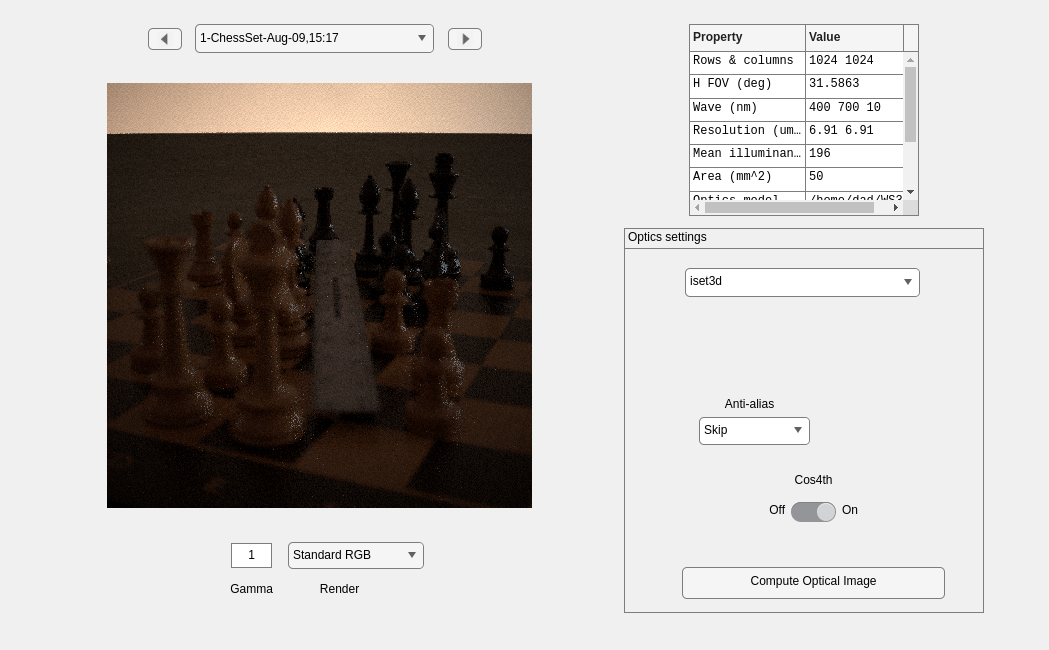

piWRS(thisR,'render type','radiance'); 

## Change the focus distance to 0.4m

User name: dad
Rendered time 520.45

------------------
Container command: docker --context default exec -it  pbrt-gpu-dad25 sh -c "cd /iset/iset3d-v4/local/ChessSet && pbrt --outfile renderings/ChessSet.exr ChessSet.pbrt"
PBRT command: pbrt --outfile renderings/ChessSet.exr ChessSet.pbrt

------------------

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 521.0 sec ***



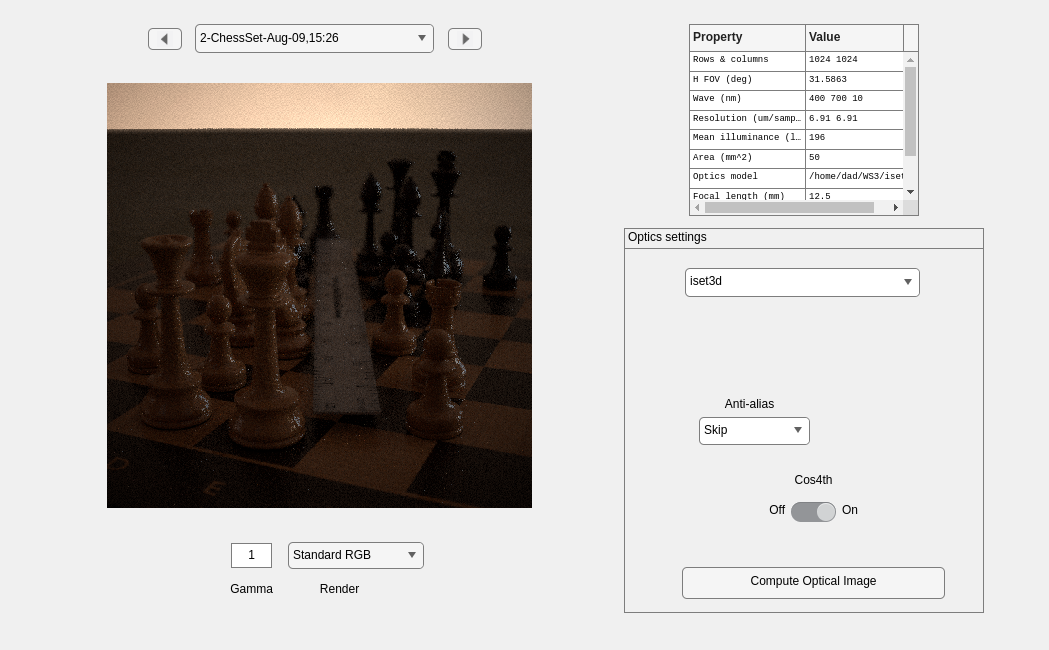

thisR.set('focus distance',0.4);
piWRS(thisR,'render type','radiance'); 